# Example

The Evolutionary Power Spectral Density (EPSD) [1] is compared to the  well-known spectrogram implemented in Matlab. The EPSD produces a smoother signal, especially if the amount of data point is low. In the following, I am using the example from [2] where the spectrogram applies well. For other application, e.g. civil engineering, the spectrogram method may provide a too low frequency or time resolution. The use of the EPSD is therefore more common in this field, see e.g. [3] for an  application of the EPSD to compute the bridge response to non-stationary wind load.  

#### References: 

[1] Priestley, M. B. (1965). Evolutionary spectra and non-stationary  processes. Journal of the Royal Statistical Society.  Series B (Methodological), 204-237. 

[2] http://www.mathworks.com/help/signal/ref/spectrogram.html  

[3] Hu, L., Xu, Y. L., & Huang, W. F. (2013).  Typhoon-induced non-stationary buffeting response of long-span bridges  in complex terrain. Engineering Structures, 57, 406-415. 

## Case of a Chirp signal 

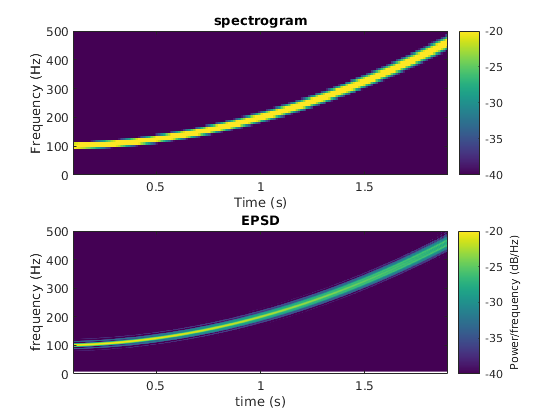


clearvars;close all;clc;
t = 0:0.001:2; % time vector
dt = median(diff(t)); % sampling time
fs=1/dt; % sampling frequency
x = chirp(t,100,1,200,'quadratic');


figure
subplot(211)
spectrogram(x,128,120,128,fs,'yaxis')
colorbar
caxis([-40,-20])
ylim([0,500])
xlim([0.1,1.9])
title('spectrogram')

subplot(212)
Nfreq=1024;
[Sp,freq,t] = EPSD(x,fs,Nfreq,'scale','lin','H',60*dt,'T',1.01*dt,'dataPlot',1);
caxis([-40,-20])
ylim([0,500])
xlim([0.1,1.9])
title('EPSD')
set(gcf,'color','w')

if exist('viridis','file'), colormap('viridis'); end % for viridis colormap

## Case of a triangle signal 

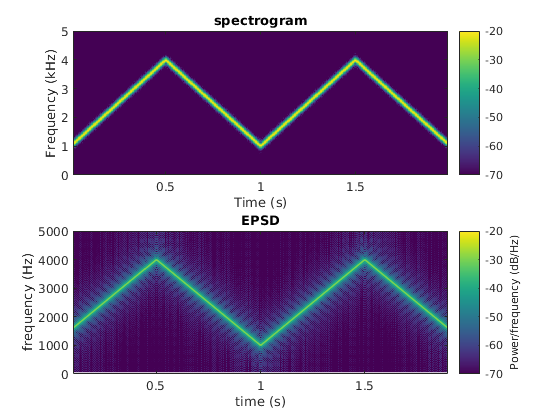

clearvars;close all;clc;
fs = 10e3; % sampling frequency
dt = 1/fs; % sampling time
t = 0:1/fs:2; % time vector
x = vco(sawtooth(2*pi*t,0.5),[0.1 0.4]*fs,fs);

figure
subplot(211)
spectrogram(x,kaiser(256,5),220,512,fs,'yaxis')
axis tight
colorbar
caxis([-70,-20])
title('spectrogram')

subplot(212)
Nfreq=1024;
[Sp,freq,t] = EPSD(x,fs,Nfreq,'scale','lin','H',80*dt,'T',1.05*dt, 'dataPlot',1);
caxis([-70,-20])
ylim([0,5e3])
xlim([0.1,1.9])
title('EPSD')
set(gcf,'color','w')
if exist('viridis','file'), colormap('viridis'); end